% ----------------------------------------------
% This code is associated with our work on the privacy perspective of the
% diffusion model. 
% The name of the variables/parameters are the same asof the paper, and we
% apply the RDP accountant with the convertion from RDP to DP to evaluate
% the privacy guarantee of the diffusion process.
% Moreover, we also compute the privacy gurantee from DP-SGD, and obtains
% the overall privacy of the whole diffusion process.
% If you have any question, 
% please feel free to reach Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

clear 
close all

% Compute the privacy gurantee lies in the diffusion (forward) process

omega = 0.01; % The input difference bound, |X_0-X'_0|<omega
T =1000; % The total steps of the forward process

% The schedule of variance for the diffusion Gaussion nosie
beta_1=1e-4;
beta_T = 0.02;
beta = linspace(beta_1,beta_T,T); 
% Compute serveral parameters of interests
% Note that we treat the mu_t(X_0) as a random variable, and the DP guarantee lies 
% in the divergence between mu_t(X_0) and mu_t(X'_0).

alpha = zeros(1,T); % alpha_t = (1-beta(1))*...*(1-beta(t))
sensitivity = zeros(1,T); 
sigma = zeros(1,T); % The standard diviation of mu_t(X_0), which is the same as mu_t(X'_0) 
alpha(1) = 1-beta(1); % initialize alpha(1)
sensitivity(1) = omega;
for i=2:T
    alpha(i) = alpha(i-1)*(1-beta(i));
    sensitivity(i) = (beta(i)*sqrt(alpha(i-1))+sqrt(1-beta(i))*(1-alpha(i-1))*sqrt(alpha(i)))/(1-alpha(i))*omega;
    sigma(i) = sqrt(1-beta(i))*(1-alpha(i-1))/sqrt(1-alpha(i));
end

% Plot the ratio of sigma/sensitivity
figure( 'Position', [0 0 800 350])

subplot(1,2,1)
plot(1:T,sigma./sensitivity,LineWidth=1.5)
xlabel("rounds",FontSize = 13)
ylabel("sigma/sen",FontSize=13)
title(sprintf("beta=[%1.1e, %1.1e], T=%d",beta_1,beta_T,T));
grid on
subplot(2,2,2)
plot(1:T,sigma,LineWidth=1.5)
xlabel("rounds",FontSize = 13)
ylabel("sigma",FontSize=13)
grid on
subplot(2,2,4)
plot(1:T,sensitivity,LineWidth=1.5)
xlabel("rounds",FontSize = 13)
ylabel("sensitivity",FontSize=13)
grid on

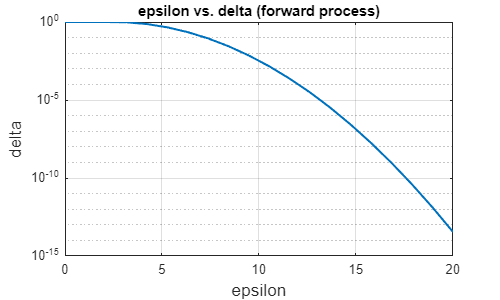

% Compute the Renyi-divergence w.r.t. orders, and
% computet the privacy guarantee lies in the forward process

RenyiDivForward = zeros(1,T);
for t = 2:T
    RenyiDivForward(t) = omega^2/2*((beta(t)*sqrt(alpha(t-1))+sqrt(1-beta(t))*(1-alpha(t-1))*sqrt(alpha(t))))^2/(1-alpha(t))./...
        (1-beta(t))./(1-alpha(t-1))^2;
end

% (order,tau) Curve for the RDP

orders = [1.1:0.1:10,11:20]; % The orders of RDP
tau_forward = orders*sum(RenyiDivForward);

zeta = 1./orders.*(1-1./orders).^(orders-1);

% Convert RDP to DP via Shabab's bound

% delta = 10.^(-10:0.2:0); % set up a grid of delta
% % search for the best epsilon among the orders of RDP
% eps = zeros(size(delta));
% for i=1:length(delta)
%     if orders*delta(i)>=1
%         eps(i) = min(max(tau+log(1-delta(i)),0));
%     end
%     if orders*delta(i)>0
%         eps(i) = min(1./(orders-1).*min(max(0,(orders-1).*tau-log(delta(i)./zeta)),log((exp(tau.*(orders-1))-1)./orders./delta(i)+1)));
%     end
% end

% Convert RDP to DP via Moments Accountant
eps = linspace(0,20,20);
delta_forward = zeros(size(eps));
for i = 1:length(eps)
    delta_forward(i) = min(exp(-(orders-1).*max(eps(i)-tau_forward,0)));
end

figure( 'Position', [0 0 500 300])
semilogy(eps,delta_forward,LineWidth=1.5)
xlabel("epsilon",FontSize=13)
ylabel("delta",FontSize=13)
title("epsilon vs. delta (forward process)")
grid on

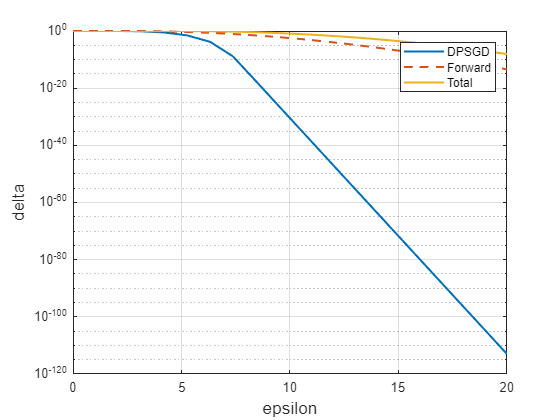

% Compute the reverse privacy guarantee lies in the DP-SGD mechanism
% using Moments Accountant.

T2=1000;
sen_reverse = 1;
sigma_dpsgd = 0.4; % The sttdev of the injected noise in dpsgd
q = 10/T; % subsampling rate
x_grid = -10:0.01:10;
f = @(x) 1/sqrt(2*pi)/sigma_dpsgd.*exp(-x.^2/2/sigma_dpsgd^2)*0.01;
p_dpsgd = f(x_grid);
q_dpsgd = q*f(x_grid-sen_reverse)+(1-q)*f(x_grid);
RenyiDivRev  = @(order)log(sum(q_dpsgd.*(p_dpsgd./q_dpsgd).^order))./(order-1);
tau_reverse =arrayfun(RenyiDivRev,orders);

delta_dpsgd = zeros(size(eps));
delta_total = zeros(size(eps));
for i = 1:length(eps)
    delta_dpsgd(i) = min(exp(-(orders-1).*max(eps(i)-tau_reverse*T2,0)));
    delta_total(i) = min(exp(-(orders-1).*max(eps(i)-(tau_reverse*T2+tau_forward),0)));
end

figure
semilogy(eps,delta_dpsgd,LineWidth=1.5)
hold on
semilogy(eps,delta_forward,'--',LineWidth=1.5)
hold on
semilogy(eps,delta_total,LineWidth=1.5)
xlabel("epsilon",FontSize=13)
ylabel("delta",FontSize=13)
legend("DPSGD","Forward","Total")
grid on